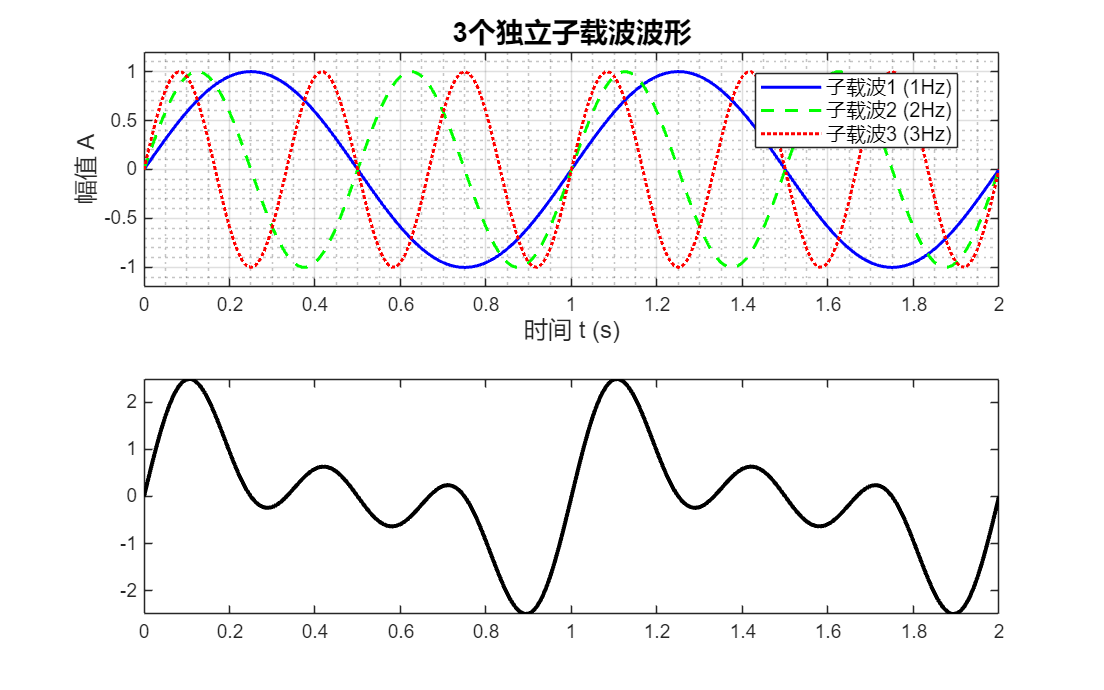

% 子载波叠加示意图（OFDM高PAPR成因）
clear; clc; close all;

%% 1. 参数设置（确保峰值叠加明显）
f_s = 100;          % 采样频率(Hz)，保证波形平滑
t = 0:1/f_s:2;      % 时间范围(0~2s)，覆盖多个周期
f = [1, 2, 3];      % 3个子载波频率(Hz)，差异适中便于区分
A = ones(1,3);      % 子载波幅值（均为1，叠加后峰值可达3）

%% 2. 计算各子载波及叠加波形
carrier1 = A(1)*sin(2*pi*f(1)*t);  % 子载波1（1Hz）
carrier2 = A(2)*sin(2*pi*f(2)*t);  % 子载波2（2Hz）
carrier3 = A(3)*sin(2*pi*f(3)*t);  % 子载波3（3Hz）
ofdm_signal = carrier1 + carrier2 + carrier3;  % 叠加后的OFDM信号

%% 3. 找到峰值叠加时刻（用于标注）
[peak_val, peak_idx] = max(ofdm_signal);  % 最大峰值及对应索引
peak_time = t(peak_idx);                  % 峰值叠加时刻

%% 4. 绘图设置（适配PPT，清晰直观）
figure('Position', [100, 100, 800, 500]);  % 画布大小（宽×高）

% 子图1：3个独立子载波（分开展示）
subplot(2,1,1);
plot(t, carrier1, 'b-', 'LineWidth', 1.5, 'DisplayName', '子载波1 (1Hz)'); hold on;
plot(t, carrier2, 'g--', 'LineWidth', 1.5, 'DisplayName', '子载波2 (2Hz)');
plot(t, carrier3, 'r:', 'LineWidth', 1.5, 'DisplayName', '子载波3 (3Hz)');
xlabel('时间 t (s)', 'FontSize', 12);
ylabel('幅值 A', 'FontSize', 12);
title('3个独立子载波波形', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 10);
grid on; grid minor;  % 网格辅助观察
ylim([-1.2, 1.2]);    % 固定幅值范围，突出子载波幅度一致性

% 子图2：叠加后的OFDM信号（突出峰值）
subplot(2,1,2);
plot(t, ofdm_signal, 'k-', 'LineWidth', 2, 'DisplayName', 'OFDM叠加信号');
hold on;

% 标注峰值叠加位置（箭头+文字）
annotation('arrow', [peak_time/2, peak_time/2], [peak_val*0.6, peak_val*0.95], ...
           'Color', 'red', 'LineWidth', 2);

错误使用 annotation (第 109 行)
X 和 Y 值必须介于 0 与 1 之间。

text(peak_time/2 - 0.1, peak_val*0.5, '峰值叠加→高PAPR', ...
     'Color', 'red', 'FontSize', 12, 'FontWeight', 'bold');
% 标注平均功率线（参考）
avg_power = mean(ofdm_signal.^2);  % 平均功率（幅值≈sqrt(avg_power)）
plot(t, ones(1,length(t))*sqrt(avg_power), 'm--', 'LineWidth', 1.5, ...
     'DisplayName', '平均功率对应幅值');
xlabel('时间 t (s)', 'FontSize', 12);
ylabel('幅值 A', 'FontSize', 12);
title('叠加后的OFDM信号（峰值显著高于平均幅值）', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 10);
grid on; grid minor;
ylim([-3.5, 3.5]);  % 预留标注空间

%% 5. 图形美化（统一风格）
set(gcf, 'Color', 'white');  % 白色背景，适配PPT
set(findall(gcf, 'Type', 'Line'), 'LineSmoothing', 'on');  % 平滑线条